X=exp9{:,2:5}

X =     5.1000    3.5000    1.4000    0.2000
    4.9000    3.0000    1.4000    0.2000
    4.7000    3.2000    1.3000    0.2000
    4.6000    3.1000    1.5000    0.2000
    5.0000    3.6000    1.4000    0.2000
    5.4000    3.9000    1.7000    0.4000
    4.6000    3.4000    1.4000    0.3000
    5.0000    3.4000    1.5000    0.2000
    4.4000    2.9000    1.4000    0.2000
    4.9000    3.1000    1.5000    0.1000


[coeff,score,latent,tsquared,explained,mu] = pca(X)

coeff =     0.3616    0.6565   -0.5810    0.3173
   -0.0823    0.7297    0.5964   -0.3241
    0.8566   -0.1758    0.0725   -0.4797
    0.3588   -0.0747    0.5491    0.7511


score =    -2.6842    0.3266   -0.0215    0.0010
   -2.7154   -0.1696   -0.2035    0.0996
   -2.8898   -0.1373    0.0247    0.0193
   -2.7464   -0.3111    0.0377   -0.0760
   -2.7286    0.3339    0.0962   -0.0631
   -2.2799    0.7478    0.1743   -0.0271
   -2.8209   -0.0821    0.2643   -0.0501
   -2.6265    0.1704   -0.0158   -0.0463
   -2.8880   -0.5708    0.0273   -0.0266
   -2.6738   -0.1067   -0.1915   -0.0559


latent =     4.2248
    0.2422
    0.0785
    0.0237


tsquared =     2.1517
    2.8103
    2.0780
    2.4466
    2.5088
    3.9568
    2.9066
    1.8463
    3.3585
    2.3383


explained =    92.4616
    5.3016
    1.7185
    0.5183


mu =     5.8433    3.0540    3.7587    1.1987



% variance is latent and is explained
la=latent./sum(latent)*100

la =    92.4616
    5.3016
    1.7185
    0.5183


explained

explained =    92.4616
    5.3016
    1.7185
    0.5183



% manual transform
sc=zscore(X)*coeff

sc =    -2.0239    0.4940    0.3196   -0.9598
   -2.0163   -0.5061   -0.2279   -0.6627
   -2.1901   -0.3181    0.1835   -0.8616
   -2.1177   -0.5856    0.1243   -0.8796
   -2.0865    0.5830    0.5273   -1.0728
   -1.7291    1.3555    0.8155   -1.0286
   -2.1762   -0.0806    0.6048   -0.9782
   -2.0000    0.2364    0.2563   -0.9505
   -2.2157   -1.0708   -0.0146   -0.7795
   -2.0338   -0.3380   -0.1581   -0.8630


% the transformed
score

score =    -2.6842    0.3266   -0.0215    0.0010
   -2.7154   -0.1696   -0.2035    0.0996
   -2.8898   -0.1373    0.0247    0.0193
   -2.7464   -0.3111    0.0377   -0.0760
   -2.7286    0.3339    0.0962   -0.0631
   -2.2799    0.7478    0.1743   -0.0271
   -2.8209   -0.0821    0.2643   -0.0501
   -2.6265    0.1704   -0.0158   -0.0463
   -2.8880   -0.5708    0.0273   -0.0266
   -2.6738   -0.1067   -0.1915   -0.0559


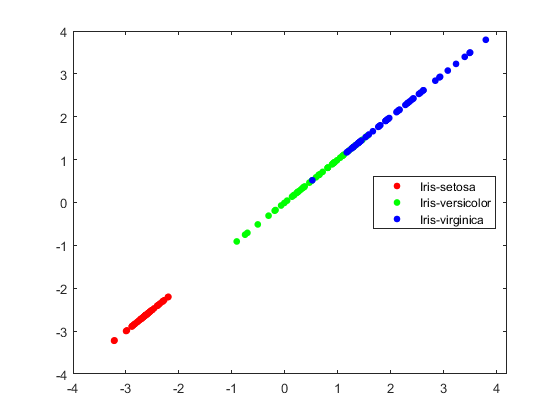

gscatter(score(:,1),score(:,1),exp9.Species)